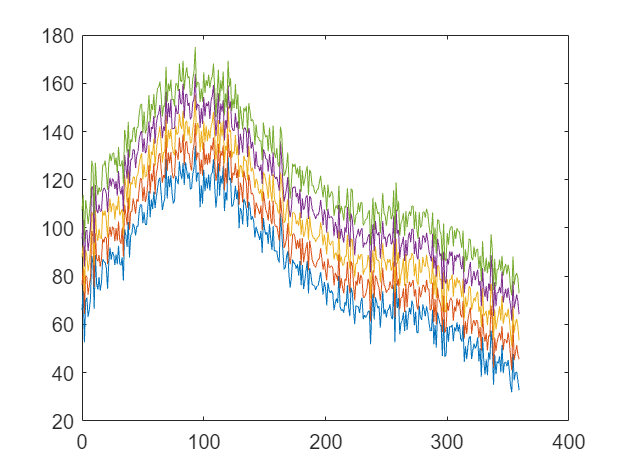

for i = 0:359
    data(i+1) = simulated_response_value(i).data;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    
end
data = repmat(data,5,1) + randn(5,360);
ang = 0:359;
plot(ang,data(1,:),ang,data(2,:)+10,ang,data(3,:)+20,ang,data(4,:)+30,ang,data(5,:)+40),

% data = mean(data,1);
% plot(ang,data),

 lik = bayes_grid_function(data).lik;
lik = lik/sum(lik,'all');
[M,I] = max(lik,[],'all'); % get maximum liklihood of parameters value and get the index of parameters
[i,j,k,h] = ind2sub(size(lik),I);


p_rp = sum(sum(sum(lik,4),3),2);
p_rp = p_rp/sum(p_rp);
p_ang = sum(sum(sum(lik,4),3),1);
p_ang = p_ang/sum(p_ang);
p_rn = squeeze(sum(sum(sum(lik,4),2),1)); 
p_rn = p_rn/sum(p_rn);
p_sig = squeeze(sum(sum(sum(lik,3),2),1));
p_sig = p_sig/sum(p_sig);

plot(110:130,p_rp,'b'),

函数或变量 'p_rp' 无法识别。

xlabel("Rpref(Hz)"), 
ylabel("probability of Rpref"),

plot(50:70,p_rn,'b'),
xlabel("Rnull(Hz)"),
ylabel("probability of Rnull"),

plot(80:100,p_ang,'b'),
xlabel("θpref"),
ylabel("probability of θpref"),

plot(70:80,p_sig,'b'),
xlabel("σ"),
ylabel("probability of σ"),